clc
close all
clearvars

Consider the system:

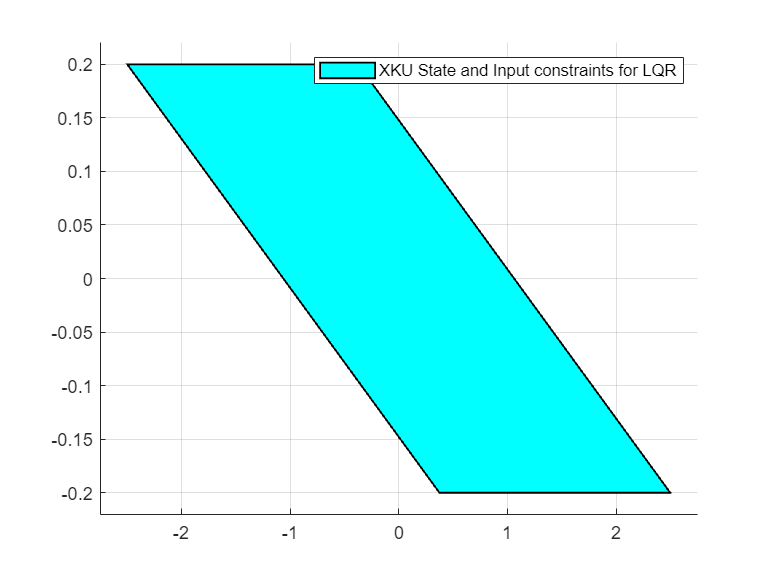

A = [0.9752 1.4544; -0.0327 0.9315];
B = [0.0248; 0.0327];
N = 10;

R = 1;
Q = 10*eye(2);
[K,Qf,e] = dlqr(A,B,Q,R);
[P,~,~]=dare(A,B,Q,R,[]);
K = -K;
% defining the constraints
% for the states
F = [-1 0 ;1 0; 0 -1;0 1];
f = [5; 5; 0.2;0.2];
% for the input
M = [-1; 1];
m = [1.75;1.75];
X = Polyhedron(F,f);
U = Polyhedron([F;M*K], [f;m]);
plot(U,'color', 'c')
legend('XKU State and Input constraints for LQR')

Acl = A +B*K;
% Compute the invariance set of the controlled system
Omega(1) = U;
for k = 2:100
    preset = Polyhedron(Omega(k-1).A*Acl, Omega(k-1).b);
    Omega(k) = intersect(preset, Omega(k-1));
    if Omega(k) == Omega(k-1)
        disp(['Invariant set found:']);
        Xf = Omega(k)
        break
    end
end

Invariant set found:


Polyhedron in R^2 with representations:
    H-rep (irredundant) : Inequalities   8 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


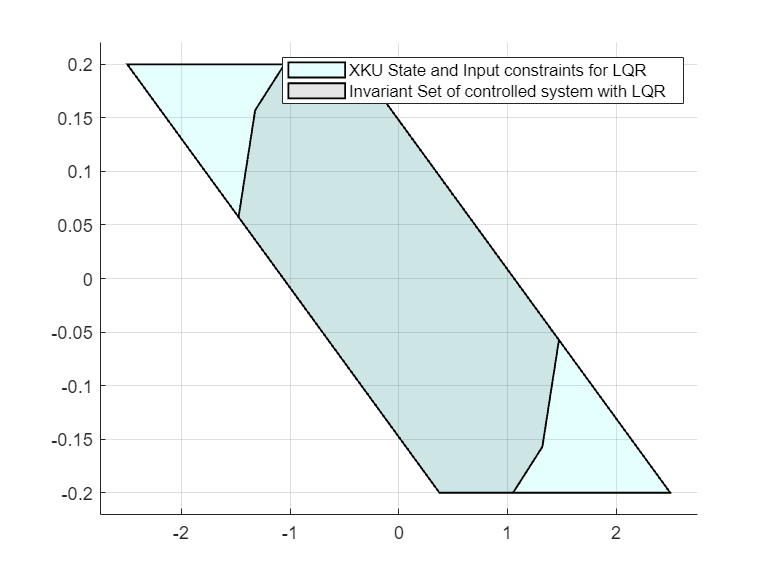

plot(U,'alpha', 0.1, 'color','c', Xf,'color', 'k','alpha', 0.1)
legend('XKU State and Input constraints for LQR', 'Invariant Set of controlled system with LQR')

Computing the feasibility set and the maximum controlled invariance

Omega(1) = X;
for k = 2:1000
    G = [Omega(k-1).A*A Omega(k-1).A*B;zeros(size(M,1),size(F*A,2)) M];
    g = [Omega(k-1).b; m];
    Constraints = Polyhedron(G, g);
    preset = projection(Constraints, 1:2);
    Omega(k) = intersect(preset, Omega(k-1));
    if k == N
        CN = Omega(k)
    end
    if Omega(k) == Omega(k-1)
        disp(['Invariant set found:']);
        CInf = Omega(k)
        break
    end
end

Polyhedron in R^2 with representations:
    H-rep (redundant)   : Inequalities  49 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


Invariant set found:


Polyhedron in R^2 with representations:
    H-rep (irredundant) : Inequalities  20 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


if k ==N
    disp(['The feasibility set for N = ', num2str(N), ' is equal to the maximum controlled invariance'])
end

The feasibility set for N = 10 is equal to the maximum controlled invariance


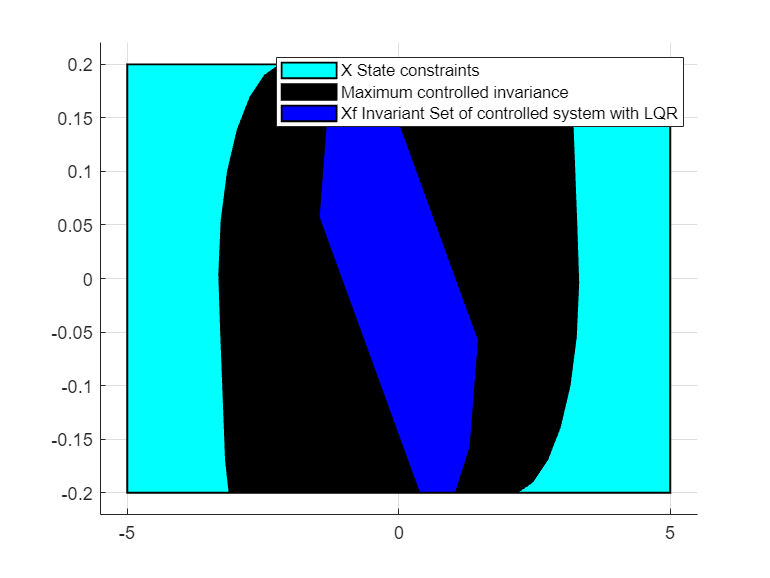

    plot(X,'alpha', 1, 'color','c', CInf,'color', 'k','alpha',1, Xf,'color', 'b','alpha', 1)
legend('X State constraints', 'Maximum controlled invariance', 'Xf Invariant Set of controlled system with LQR')

sys = LTISystem('A',A,'B',B);

sys.x.max = [5; 0.2];
sys.x.min = [-5; -0.2];
sys.u.min = [-1.75];
sys.u.max = [1.75];
sys.x.penalty = QuadFunction(Q);
sys.u.penalty = QuadFunction(R);

K_matlab = sys.LQRGain

K_matlab =    -1.6478  -11.8344


assert(all((K-K_matlab)<=1e-6))
Qf_Matlab = sys.LQRPenalty.weight

Qf_Matlab =    37.0252   68.3850
   68.3850  407.1177


assert(all(all((Qf-Qf_Matlab)<=1e-6)))
Xf_Matlab = sys.LQRSet

Iteration 1...
Iteration 2...
Iteration 3...
Polyhedron in R^2 with representations:
    H-rep (irredundant) : Inequalities   8 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


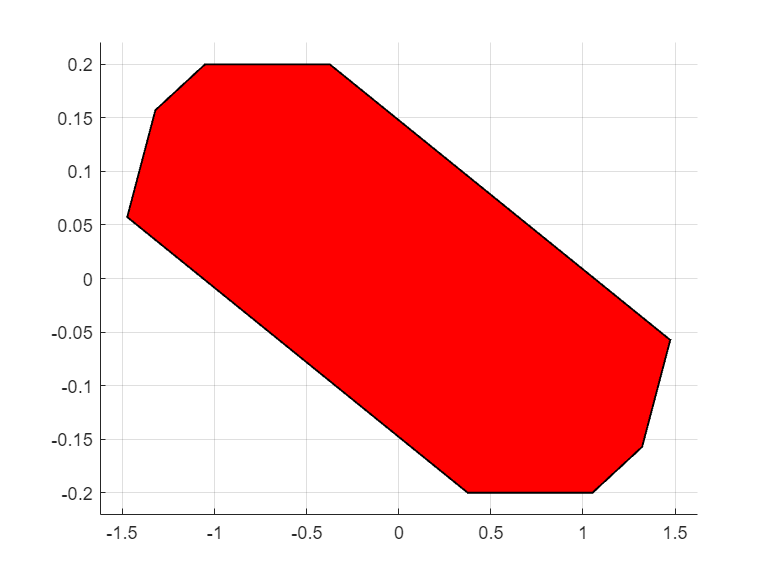

plot(Xf_Matlab)

assert(Xf_Matlab==Xf)

model.x.terminalPenalty = QuadFunction(Qf)

model = struct with fields:
    x: [1×1 struct]


model.x.terminalSet = Xf

model = struct with fields:
    x: [1×1 struct]


controller = MPCController(sys, N)

MPC controller (horizon: 10)


## **Using quadratic programming**

**Build matrixes for MPC quadratic programming optimization with function quadprog**

n = size(A,2); %number of states
nu = size(B, 2); %number of imputs
T = [kron(eye(N),eye(n)) + [zeros(n,n*N); kron(eye(N-1),-A) zeros((N-1)*n,n)]];
T = [T kron(eye(N),-B)];
t = [A;zeros((N-1)*n,n)];
H = blkdiag(kron(eye(N-1),Q), Qf, kron(eye(N),R));
h = zeros(size(H,1),1);

Ff = Xf.A;
ff = double(Xf.b);
G = blkdiag(kron(eye(N-1),F), Ff, kron(eye(N),M));
g = [repmat(f,N-1,1);ff;repmat(m,N,1)];


**Simulate the system**

%x0 = [3;0]; %using mosek, there are numerical errors
x0 = [2;-0.17];
x =[];
x(:,1) = x0;
jj = 1;
u = [];
%Simulate the system up to convergence to origin, identified by 1e-3:

while norm(x(:,end))>1e-3
    %every iteration the optimal control low is computed 
    [zopt, fval, flag] = quadprog(H, h, G, g, T, t*x(:,jj));
    if flag ~= 1
          error('Error in optimizer - could not solve the problem'); 
    end
    u(:,jj) = zopt(n*N+1:n*N+nu);
    x(:,jj+1) = A*x(:,jj)+B*u(:,jj);
    jj = jj+1;
    
end

 


**Plotting the results on time axes**

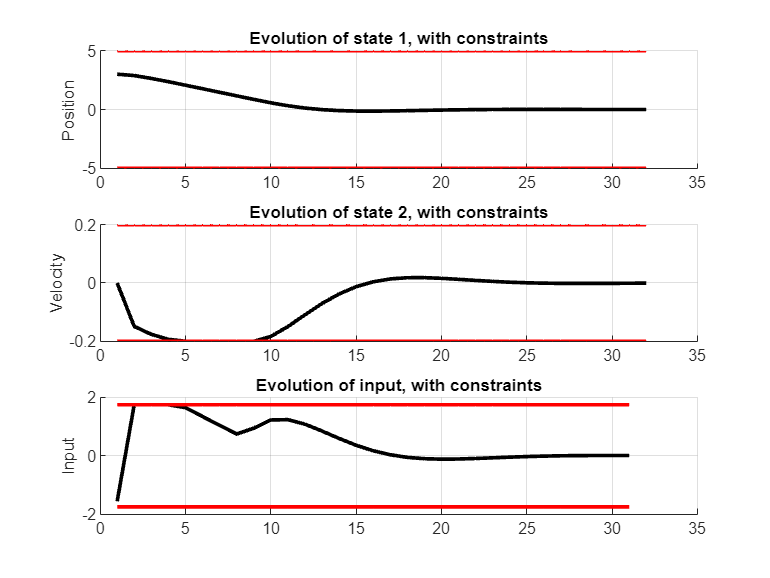


figure
hold on; grid on;

o = ones(1,size(x,2));

subplot(3,1,1)
hold on; grid on;
plot(x(1,:),'-k','markersize',20,'linewidth',2);
plot(1:size(x,2),f(1)*o,'r','linewidth',2)
plot(1:size(x,2),-f(2)*o,'r','linewidth',2)
ylabel('Position')
title('Evolution of state 1, with constraints')
subplot(3,1,2)
hold on; grid on;
plot(x(2,:),'-k','markersize',20,'linewidth',2);
plot(1:size(x,2),f(3)*o,'r','linewidth',2)
plot(1:size(x,2),-f(4)*o,'r','linewidth',2)
ylabel('Velocity')
title('Evolution of state 2, with constraints')

subplot(3,1,3)
o = ones(1,size(u,2));
hold on; grid on;
plot(u,'k','markersize',20,'linewidth',2);
plot(1:size(u,2),m(1)*o,'r','linewidth',2)
plot(1:size(u,2),-m(2)*o,'r','linewidth',2)
ylabel('Input')
title('Evolution of input, with constraints')

**Plotting the results state space**

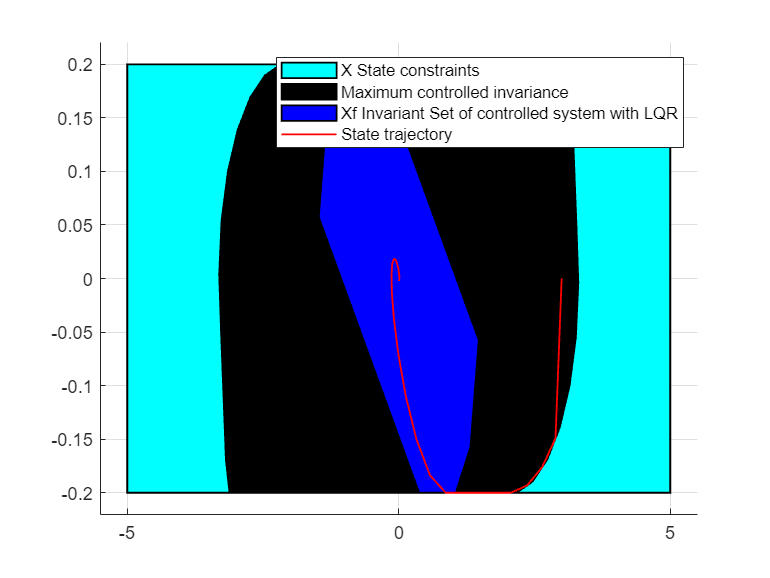

figure

hold on
plot(X,'alpha', 1, 'color','c', CInf,'color', 'k','alpha',1, Xf,'color', 'b','alpha', 1)
plot(x(1,:), x(2,:),'-r','markersize',20,'linewidth',1);
legend('X State constraints', 'Maximum controlled invariance', 'Xf Invariant Set of controlled system with LQR', 'State trajectory')
%plot(3,0,'xr')
hold off
grid on

## **Using YALMIP**

**Simulate the system**

tic
x = [];
%x0 = [2;-0.17];
%x0 = [2.5;0];
x0 = [3,0];
x(:,1) = x0;
jj = 1;
u = [];
%Simulate the system up to convergence to origin, identified by 1e-3:
%options = sdpsettings('solver', 'mosek','verbose',0);
% Define optimization variables
x_solver = sdpvar(2,N,'full');
u_solver=[];
u_solver = sdpvar(1,N,'full');
% Define constraints and objective
con = [];
obj = 0;
%con = (M*u_solver(:,1) <=m);
for i = 1:N-1
    con = [con, x_solver(:,i+1) == A*x_solver(:,i) + B*u_solver(:,i)]; % System dynamics
    if i~=1
    con = [con, F*x_solver(:,i) <= f]; % State constraints
    end
    con = [con, M*u_solver(:,i) <= m]; % Input constraints
    obj = obj + x_solver(:,i)'*Q*x_solver(:,i) + u_solver(:,i)'*R*u_solver(:,i); % Cost function
end
con = [con, Ff*x_solver(:,N) <= ff]; % Terminal constraint
obj = obj + x_solver(:,N)'*Qf*x_solver(:,N); % Terminal weight
% Compile the matrices
ctrl = optimizer(con, obj, sdpsettings('solver','sedumi'),x_solver(:,1), u_solver(:,1));
    
while norm(x(:,end))>1e-3
    
    % Can now compute the optimal control input using
    [uopt,isfeasible] = ctrl(x(:,jj));
    if isfeasible == 1
          error('Error in optimizer - could not solve the problem'); 
    end
    u(:,jj) = uopt;
    x(:,jj+1) = A*x(:,jj)+B*u(:,jj);
    jj = jj+1;
    
end

toc

Elapsed time is 2.440485 seconds.


**Plotting the results on time axes**

figure
hold on; grid on;

o = ones(1,size(x,2));

subplot(3,1,1)
hold on; grid on;
plot(x(1,:),'-k','markersize',20,'linewidth',2);
plot(1:size(x,2),f(1)*o,'r','linewidth',2)
plot(1:size(x,2),-f(2)*o,'r','linewidth',2)
ylabel('Position')
title('Evolution of state 1, with constraints')
subplot(3,1,2)
hold on; grid on;
plot(x(2,:),'-k','markersize',20,'linewidth',2);
plot(1:size(x,2),f(3)*o,'r','linewidth',2)
plot(1:size(x,2),-f(4)*o,'r','linewidth',2)
ylabel('Velocity')
title('Evolution of state 2, with constraints')

subplot(3,1,3)
o = ones(1,size(u,2));
hold on; grid on;
plot(u,'k','markersize',20,'linewidth',2);
plot(1:size(u,2),m(1)*o,'r','linewidth',2)
plot(1:size(u,2),-m(2)*o,'r','linewidth',2)
ylabel('Input')
title('Evolution of input, with constraints')

**Plotting the results state space**

figure

hold on
plot(X,'alpha', 1, 'color','c', CInf,'color', 'k','alpha',1, Xf,'color', 'b','alpha', 1)
plot(x(1,:), x(2,:),'-r','markersize',20,'linewidth',1);
legend('X State constraints', 'Maximum controlled invariance', 'Xf Invariant Set of controlled system with LQR', 'State trajectory')
%plot(3,0,'xr')
hold off
grid on

## Explicit MPC

tic
empc = controller.toExplicit()

regions:  107, unexplored: 6 
mpt_plcp: 137 regions
Explicit MPC controller (horizon: 10, regions: 137)


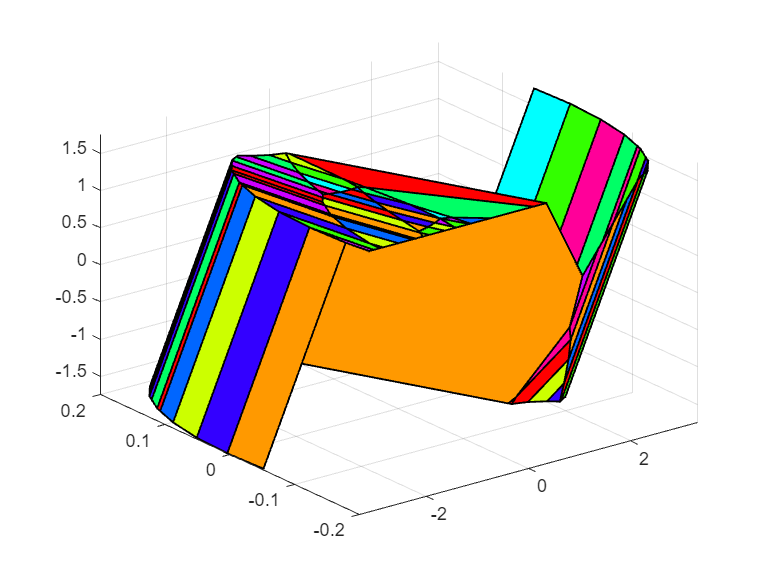

empc.feedback.fplot()

**Simulate the system**

x0 = [3,0];
x_mpc = [];
x_mpc(:,1) = x0';

u_mpc = [];
i = 1;
while norm(x_mpc(:,end))>1e-3
    u_mpc(:,i) = empc.evaluate(x_mpc(:,i));
    
    x_mpc(:,i+1) = A*x_mpc(:,i) + B*u_mpc(:,i);

    i = i + 1;
end
toc

Elapsed time is 0.342820 seconds.


**Plotting the results on time axes**

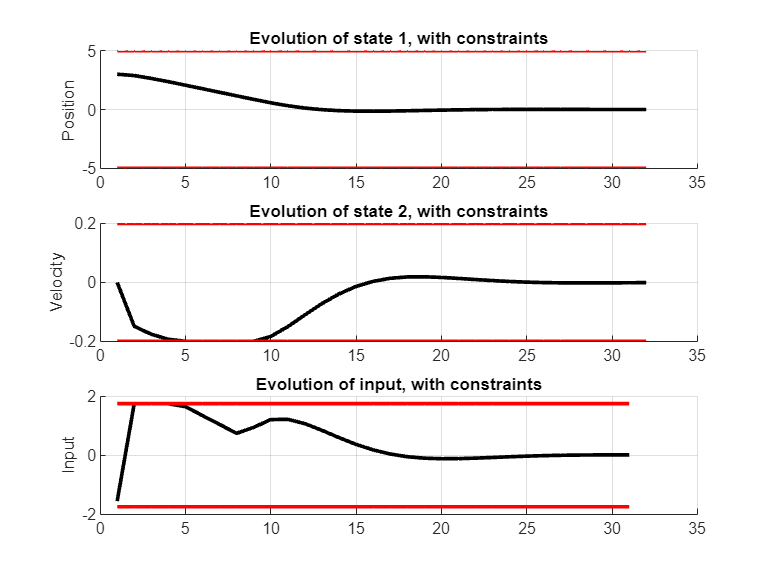

figure
hold on; grid on;

o = ones(1,size(x_mpc,2));

subplot(3,1,1)
hold on; grid on;
plot(x_mpc(1,:),'-k','markersize',20,'linewidth',2);
plot(1:size(x_mpc,2),f(1)*o,'r','linewidth',2)
plot(1:size(x_mpc,2),-f(2)*o,'r','linewidth',2)
ylabel('Position')
title('Evolution of state 1, with constraints')
subplot(3,1,2)
hold on; grid on;
plot(x_mpc(2,:),'-k','markersize',20,'linewidth',2);
plot(1:size(x_mpc,2),f(3)*o,'r','linewidth',2)
plot(1:size(x_mpc,2),-f(4)*o,'r','linewidth',2)
ylabel('Velocity')
title('Evolution of state 2, with constraints')

subplot(3,1,3)
o = ones(1,size(u_mpc,2));
hold on; grid on;
plot(u_mpc,'k','markersize',20,'linewidth',2);
plot(1:size(u_mpc,2),m(1)*o,'r','linewidth',2)
plot(1:size(u_mpc,2),-m(2)*o,'r','linewidth',2)
ylabel('Input')
title('Evolution of input, with constraints')

**Plotting the results state space**

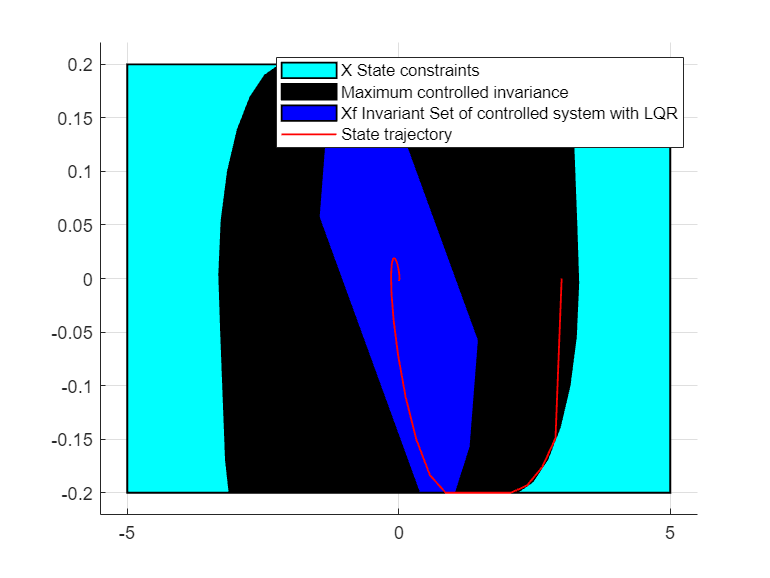

figure

hold on
plot(X,'alpha', 1, 'color','c', CInf,'color', 'k','alpha',1, Xf,'color', 'b','alpha', 1)
plot(x_mpc(1,:), x_mpc(2,:),'-r','markersize',20,'linewidth',1);
legend('X State constraints', 'Maximum controlled invariance', 'Xf Invariant Set of controlled system with LQR', 'State trajectory')
%plot(3,0,'xr')
hold off
grid on